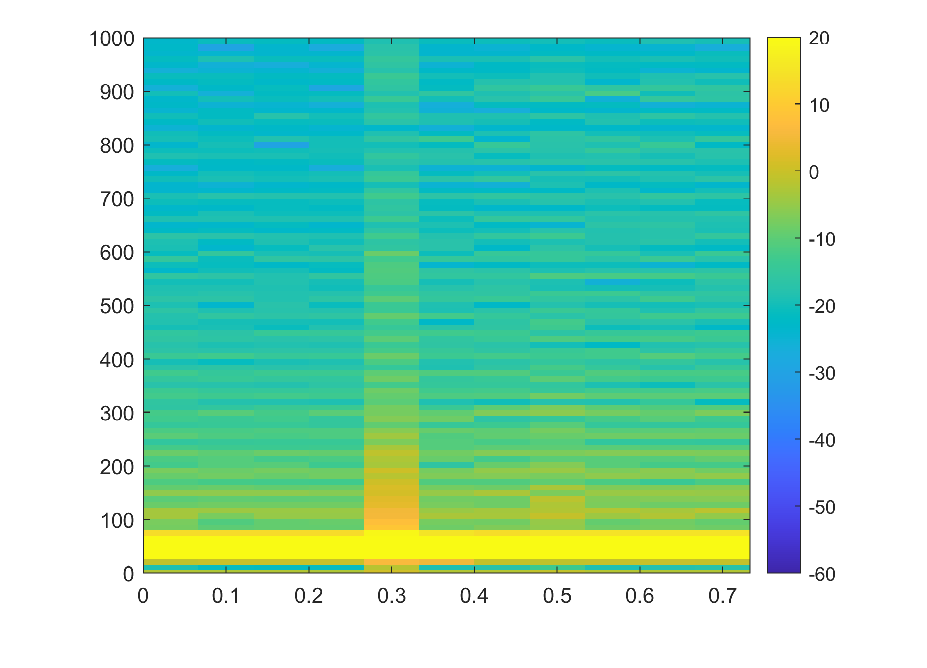

clc
clear all;
load('bestModel.mat','bestNet');
% Example usage of classifyNewImage:

[label,prob]= classifyNewImage(bestNet, 'C:\Users\Dell\Desktop\Project MSC Third Sem\MATLAB Files\Scripts\testimages\4is.png');

label= char(label);
prob=prob*100;
if label=="Islanding"
    message= " Islanding Condition Detected"
    message1="The confidence level of classification is" + prob
else
    message=" The abnormality in voltage waveform doesnot correspond to islanding condition"
    message1="The confidence level of classification is " + prob
end

message = " Islanding Condition Detected"

message1 = "The confidence level of classification is99.5984"

function preprocessedImg = preprocessImage(img)
    % Resize image to a smaller dimension
    img = imresize(img, [224 224]);
    % Convert to single precision and scale to [0, 1]
    img = im2single(img);
    % Normalize to zero mean and unit variance
    img = (img - mean(img(:))) / std(img(:));
    preprocessedImg = img;
end
function [label, probability] = classifyNewImage(net, imagePath)
    img = imread(imagePath);
    imshow(img)
    img = preprocessImage(img);
    
%     % Get the input size from the network's input layer
%     inputSize = net.layers(1).InputSize;
%     
%     % Ensure the image matches the network's input size
%     if ~isequal(size(img), inputSize)
%         img = imresize(img, inputSize(1:2));
%     end
    
    % Classify the image
    [label, scores] = classify(net, img);
    probability = max(scores);
    end
